# Histogram

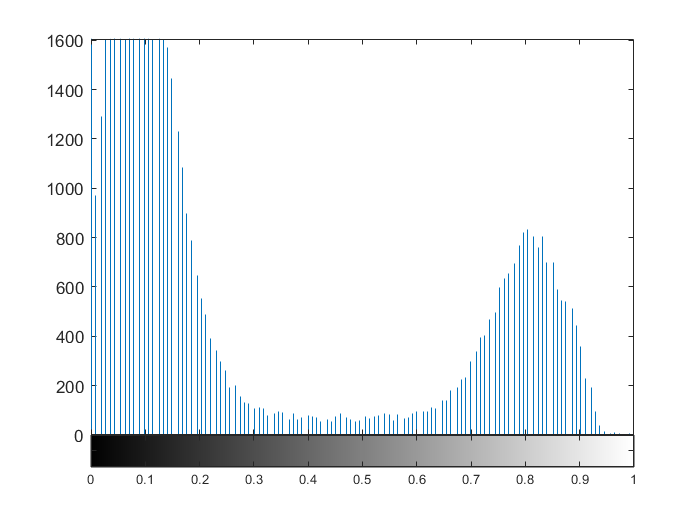

f = imread('chest-xray.tif');
imhist(f);
figure;
imhist(f,20);

clear;
close all;
im=imread('rice.gif');
imshow(im);
figure;
imhist(im);
im=mat2gray(im); % transform to set range to [0,1]
figure;
imshow(im);
figure;
imhist(im);

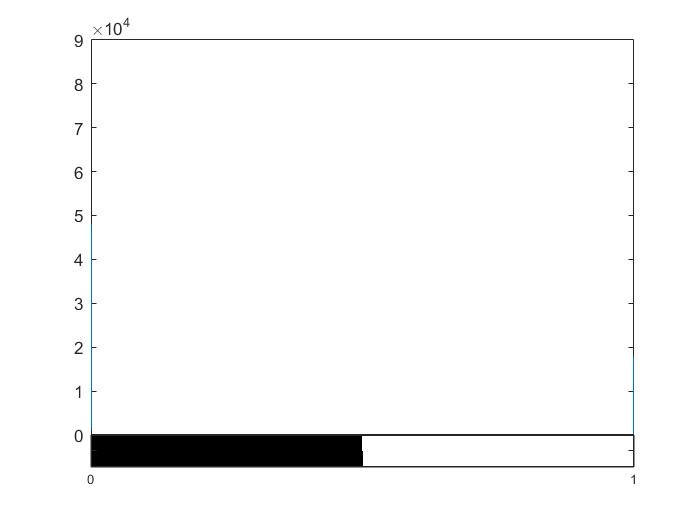

im=imread('rice.gif');
imhist(im)
T=graythresh(im); % matlab calculates the threshold value T (check matlab help)
im=im2bw(im,T); % transforms into black white image according to threshold T
figure;
imshow(im);
figure;
imhist(im);

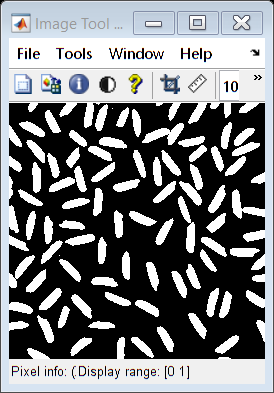


%same with rice.jpg

im=imread('rice.jpg');
imshow(im);
figure;
imhist(im);
im=mat2gray(im); % transform to set range to [0,1]
figure;
imshow(im);
figure;
imhist(im);
im=imread('rice.jpg');
T=graythresh(im); % matlab calculates the threshold value T (check matlab help)
im=im2bw(im,T); % transforms into black white image according to threshold T
figure;
imshow(im);
figure;
imhist(im);


im=imread('rice.gif');
im= imbinarize(im);
 [L,n]=bwlabel(im);
imtool(L);


D=regionprops(L,'Centroid');


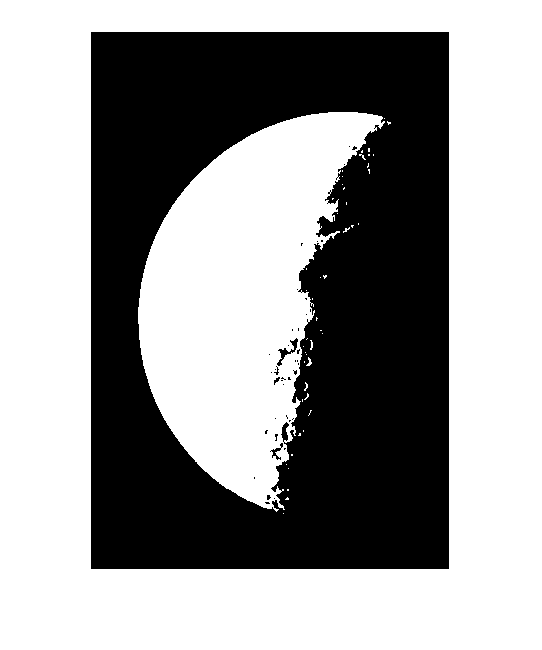

clear;
close all;
im=imread('moon.tif');
im = imbinarize(im);
imshow(im);

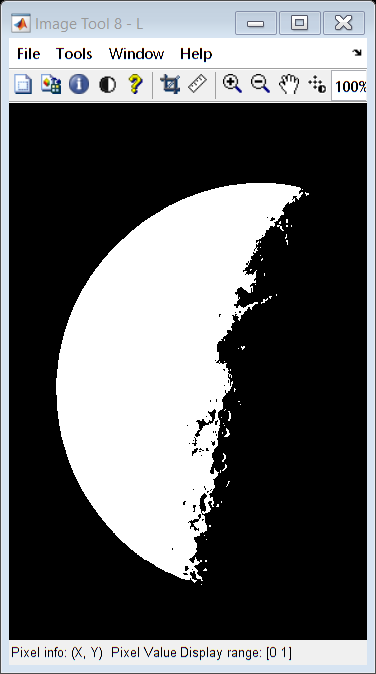

[L,n]=bwlabel(im);
imtool(L);

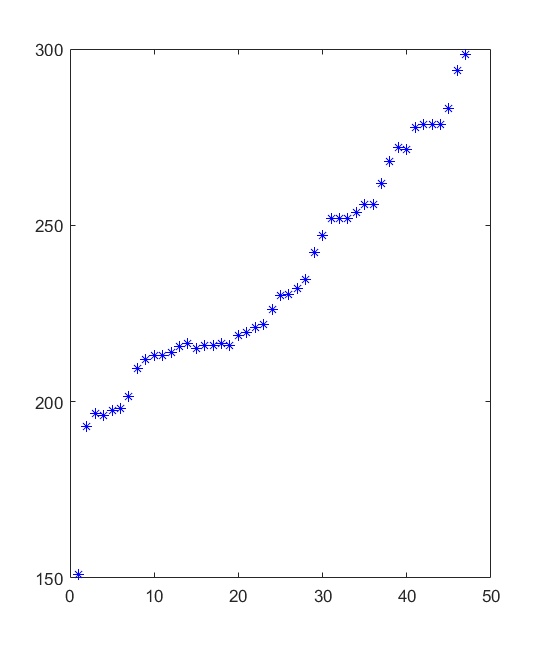

D=regionprops(L,'Centroid'); 
centroids = cat(1, D.Centroid); %returns the x,y coordinates from the centroids
plot(centroids(:,1), 'b*')      %print the x coordinates of the controids

D(1)

ans = struct with fields:
    Centroid: [151.1066 263.6220]


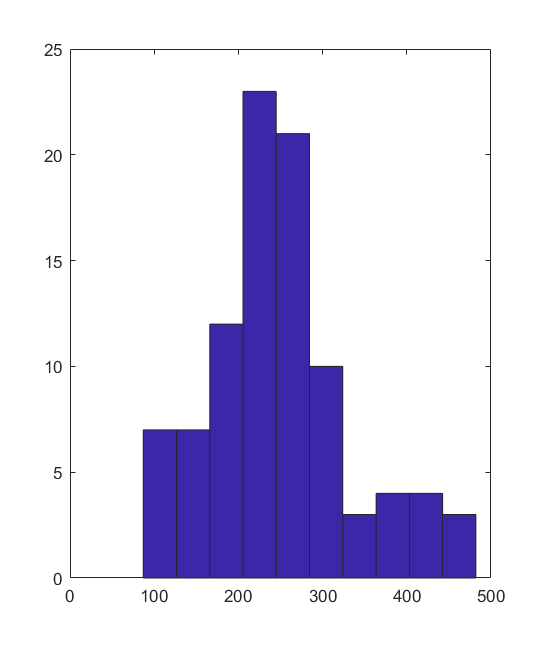

w=struct2array(D);
meancentroid=mean(w);
Stdcentroid=std(w);
hist(w) 